clear; clc; clf;

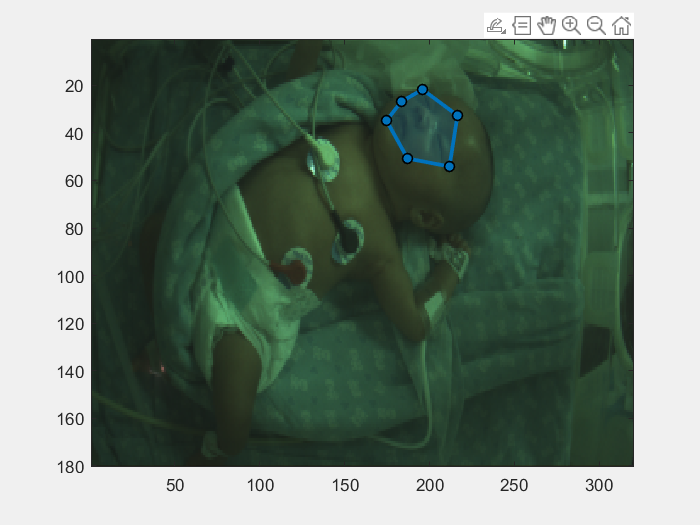


% 读取数据
fileName = "./baby.bin";
frameNum = readBinFrame(fileName, 0);
im = readBinFrame(fileName, 1); % 定义帧索引

imagesc(uint8(im(:,:,:))); drawnow;
roi = drawpolygon('Color', [0 0.4470 0.7410]); % 定义一个多边形区域

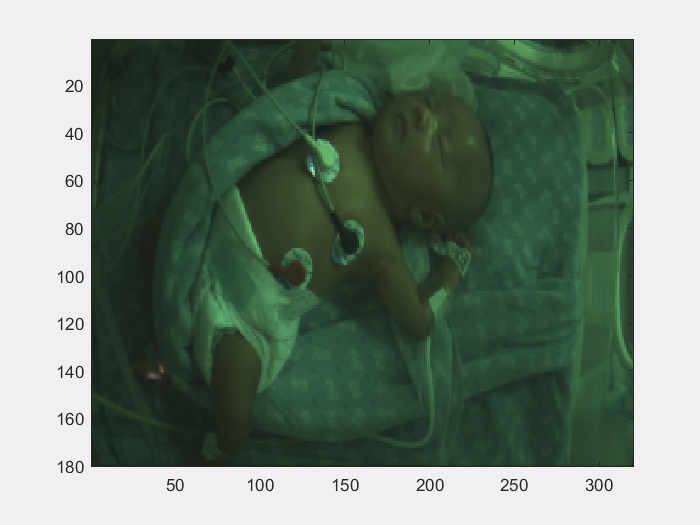

mask = createMask(roi);
[rows, cols] = find(mask);
minR = min(rows);
maxR = max(rows);
minC = min(cols);
maxC = max(cols);

% 将ROI分割成6个小块
numBlocks = 6;
blockSizeR = floor((maxR - minR + 1) / sqrt(numBlocks));
blockSizeC = floor((maxC - minC + 1) / sqrt(numBlocks));

blockMasks = cell(numBlocks, 1);
idx = 1;

for i = minR:blockSizeR:maxR
    for j = minC:blockSizeC:maxC
        if idx > numBlocks
            break;
        end
        blockMask = false(size(mask));
        blockMask(i:min(i + blockSizeR - 1, maxR), j:min(j + blockSizeC - 1, maxC)) = true;
        blockMasks{idx} = blockMask & mask;
        idx = idx + 1;
    end
    if idx > numBlocks
        break;
    end
end

rgbData = cell(numBlocks, 1);

for idx = 1:frameNum
    im = readBinFrame(fileName, idx);
    imagesc(uint8(im(:,:,:))); drawnow;
    B = im(:,:,1);
    G = im(:,:,2);
    R = im(:,:,3);

    for m = 1:numBlocks
        blockMask = blockMasks{m};
        c_r = mean(R(blockMask));
        c_g = mean(G(blockMask));
        c_b = mean(B(blockMask));
        rgbData{m} = [rgbData{m}; c_r, c_g, c_b];
    end
end

% 处理每个块的RGB数据
RGBblocks = cell(numBlocks, 1);
filteredRGB = cell(numBlocks, 1);
signal = cell(numBlocks, 1);

for n = 1:numBlocks
    RGBblocks{n} = rgbData{n};
    filteredRGB{n} = process_ppg(RGBblocks{n});
    signal{n} = process_POS(filteredRGB{n});
end


% 计算SNR
SNR = [];
for i = 1:numBlocks
    tmp = signal{i};
    F = fft(tmp, [], 2);
    S = abs(F(:, 1:floor(end / 2)));
    snr = max(S, [], 2) ./ (sum(S, 2) - max(S, [], 2));
    SNR = [SNR; snr];
end
[~, bestSignalIdx] = max(SNR);
bestSignal = signal{bestSignalIdx};

disp(['最佳信号索引: ', num2str(bestSignalIdx)])

最佳信号索引: 3


disp(['最大SNR: ', num2str(max(snr))])

最大SNR: 0.0097336


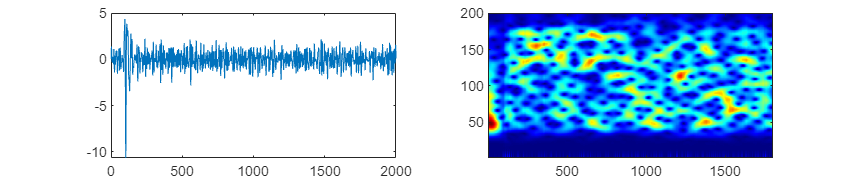


% 显示图像
[signalSpc, ~] = spec(bestSignal, 20);
figure, set(gcf, 'Position', [100 100 1200 250]); colormap('jet');
subplot(1, 2, 1);
plot(bestSignal);
subplot(1, 2, 2);
imagesc(signalSpc(1:200, :)); set(gca, 'YDir', 'normal');

function [spc, rate] = spec(signal, fps)
 % define parameter
 L = fps * 10;
 
 S = zeros(size(signal,2)-L+1,L);
 
 for idx = 1:size(signal,2)-L+1
 p = signal(1,idx:idx+L-1);
 S(idx,:) = (p-mean(p))/(eps+std(p));
 end
 
 S = S-repmat(mean(S,2),[1,L]);
 S = S .* repmat(hann(L)',[size(S,1),1]);
 S = abs(fft(S,fps*60,2));
 spc = S(:,1:fps*60/2)';
 [~, rate] = max(spc,[],1);
 rate = rate - 1;
 
end

function P = process_POS(signal)
s = [0, 1, -1; -2, 1, 1] * signal; % POS projection system
p= [1, std(s(1,:))/std(s(2,:))] * s; % plus
P(:) = (p-mean(p))/std(p);
end

function filteredSignal = process_ppg(data)
R = data(:,1);
G = data(:,2);
B = data(:,3);
normalized_R = R./mean(R)-1;
normalized_G = G./mean(G)-1;
normalized_B = B./mean(B)-1;
% 归一化和带通滤波
fs = 20; % 采样频率
f_low = 0.6; % 带通滤波器的下限
f_high = 3.0; % 带通滤波器的上限
[b, a] = butter(4, [f_low, f_high] / (fs / 2), 'bandpass');
filtered_R = filtfilt(b,a,normalized_R);
filtered_G = filtfilt(b,a,normalized_G);
filtered_B = filtfilt(b,a,normalized_B);
filteredSignal = [];
filteredSignal(:,1) = filtered_R; 
filteredSignal(:,2) = filtered_G; 
filteredSignal(:,3) = filtered_B;
filteredSignal = filteredSignal';
end